
L=12;
k = sym('k',[1 L/2]) ;

syms K(z);
K(z)=1*z^(0);
for i=(1:L/2)
    K(z)=K(z)+k(i)*(z^(2*i-1)+z^(-(2*i-1)));
end



eqn=[];
eqn=[K(-1)==0];
d=K(z);
for i=1:(L-1)
    d=diff(d);
    z=-1;    
    eqn=[eqn subs(d)==0];
end



[A,B] = equationsToMatrix(eqn, k);
A=double(A)';B=double(B)';
[R,basiccol] = rref(A);
A = double(A(:,basiccol)');
B = double(B(:,basiccol))';

k=linsolve(A,B)';

syms z;
K=1*z^(0+(L-1));
for i=(1:L/2)
    K=K+k(i)*(z^((2*i-1)+(L-1))+z^(-(2*i-1)+(L-1)));
end

roots=vpa(solve(K,z));
[roots_new,Index] = sort(abs(roots));
Index = Index(1:length(Index)/2);
roots = roots(Index)

$$roots = \left(\begin{array}{c} 0.35254298476320980390398275070881\\ 0.33711562223300934383855481365925-0.15638426950206276237033740735479\,\mathrm{i}\\ 0.33711562223300934383855481365925+0.15638426950206276237033740735479\,\mathrm{i}\\ 0.2693787360402730923503217744004-0.35469814824108441642672419467905\,\mathrm{i}\\ 0.2693787360402730923503217744004+0.35469814824108441642672419467905\,\mathrm{i}\\ -0.92891590736286820306152728564435-0.018276916364177337135009522676939\,\mathrm{i}\\ -0.92891590736286820306152728564435+0.018276916364177337135009522676939\,\mathrm{i}\\ -0.94613985921854750569970978562399-0.05097569467488161947376434164596\,\mathrm{i}\\ -0.94613985921854750569970978562399+0.05097569467488161947376434164596\,\mathrm{i}\\ -0.97777424017459154542727897562473-0.072127455487162807215601441703056\,\mathrm{i}\\ -0.97777424017459154542727897562473+0.072127455487162807215601441703056\,\mathrm{i} \end{array}\right)$$

% roots = roots(1:length(roots)/2);
% roots=[-1*ones(1,L/2) roots(abs(roots)<=1)'];

%poly(roots)


poly = flip(coeffs(expand(prod(sym('z')-roots))));
poly=poly/sqrt(sumsqr(abs(poly)));

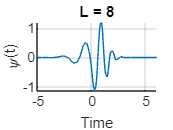



x=poly;
t=[];legendInfo=[];
hold on
for i=(1:17)
    x=nthroot(2,L)*conv(double(real(upsample(x,2))),double(real(poly)));
    x=x(1:end-1);
    t=(0:1/2^(i+1):(L-1)*(1-1/2^(i+1)))';
    wavelet=((-1).^(0:L-1)).*flip(double(real(poly)));
    
    y_main =  x;
    y_main = wavelet(1)*y_main;
    %plot(y_main)
    y_sub = x;
    for j =(1:L-1)
        y_main = [y_main zeros(1,int32((1*length(x))/(L-1)))];
        y_sub = [zeros(1,int32((1*length(x))/(L-1))) y_sub];
       
        y_main=y_main + wavelet(j+1)*y_sub;
        %plot(y_main)
        %plot(y_sub
    end
    hr = y_main;
    if (i==17)
        plot(linspace(1-L/2,L-1+1-L/2,length(hr)),hr*1.2/max(hr));
    end
end
hold off
grid on
% 
% legend(["iteration 1","iteration 2","iteration 3","iteration 5","iteration 10","iteration 15","iteration 17"])

% xlim([0.00 7.00])
% ylim([-0.6 1.5])
xlabel("Time")
ylabel("\phi(t)")


title("L = 8")

ylabel("\psi(t)")

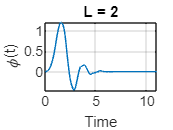


% xlim([-0.80 1.68])
% ylim([-0.75 1.02])
% title("L = 4")
% 
% xlim([-2.00 3.00])
% ylim([-0.78 1.20])
% title("L = 6")
% 
% xlim([-3.00 4.00])
% ylim([-0.82 1.20])
% title("L = 8")


plot(t,x*1.2/max(x));
xlabel("Time")
ylabel("\phi(t)")
title("L = 2")
grid on

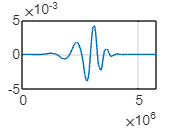

wavelet=[(-1).^(0:L-1)].*flip(double(real(poly)));
% 
% y=[wavelet(1)*x(1:length(x)/2)];tt=[t(1:length(t)/2)'];
% 
% for i=(1:L-1)
%     y=[y wavelet(i)*x(length(x)/2+1:end)+wavelet(i+1)*x(1:length(x)/2)];
%     tt=[tt tt(end)+t(1:length(t)/2)'];
% end
% y=[y wavelet(L)*x(length(x)/2+1:end)];
% tt=[tt tt(end)+t(1:length(t)/2)'];tt=tt/2;
% %size(y),size(tt'),size(t),size(x);
% plot(tt',y);
x_values = t;
y_values = x;

% phi_2t_x = x_values/2;
% phi_2t1_x = phi_2t_x + 0.5;
% plot(phi_2t_x,y_values,'.')
% plot(phi_2t1_x,y_values,'.')

y_main =  [y_values];
y_main = wavelet(1)*y_main;
%plot(y_main)
y_sub = [y_values];
for i =(1:L-1)
    y_main = [y_main zeros(1,int32((1*length(y_values))/(L-1)))];
    y_sub = [zeros(1,int32((1*length(y_values))/(L-1))) y_sub];
   
    y_main=y_main + wavelet(i+1)*y_sub;
    %plot(y_main)
    %plot(y_sub)
    
end
plot(y_main)
%plot(circshift(y_main,int32(length(y_main)/L)))
grid on

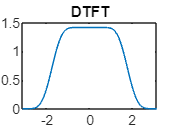

%plot(abs(dtft(double(real(poly)),L,(0:0.001:pi))));
w = -1*pi:0.01:1*pi;
n=L;
coeff=double(real(poly));
X = dtft(coeff, n, w);

plot(w, abs(X)); title('DTFT');

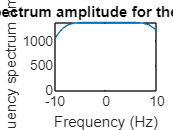


u=fftshift(fft([x zeros(1,length(x))]));   % apply Fourier transform and move zero frequency component to the center
N=length(u);         		% measure frequency range 
n=-(N-1)/2:(N-1)/2;  	% evenly divide frequency range around zero frequency
plot(n,abs(u));  			% visualize the signal in time domain 
title('Frequency spectrum amplitude for the rectangular pulse'); 
                              % set title of the plot 
xlabel('Frequency (Hz)');  	% label x-axis
ylabel('Frequency spectrum amplitude');  % label y-axis
axis([-10 10 0 max(abs(u))]); 	% set display range of x- and y-axis

% y=fftshift(fft([y_main zeros(1,length(y_main))]));   % apply Fourier transform and move zero frequency component to the center
% N=length(y);         		% measure frequency range 
% n=-(N-1)/2:(N-1)/2;  	% evenly divide frequency range around zero frequency
% f=sqrt(y.*conj(y)); 	% calculate amplitude of the frequency signal
% plot(n,f);  			% visualize the signal in time domain 
% title('Frequency spectrum amplitude for the rectangular pulse'); 
%                               % set title of the plot 
% xlabel('Frequency (Hz)');  	% label x-axis
% ylabel('Frequency spectrum amplitude');  % label y-axis
% axis([-10 10 0 max(abs(y))]); 	% set display range of x- and y-axis

% hold on
% 
% plot(w, D2);
% plot(w, D4);
% plot(w, D6);
% plot(w, D8);
% plot(w, D10);
% plot(w, D12);
% hold off

% hold on
% 
% plot(N2, F2);
% plot(N4, F4);
% plot(N6, F6);
% plot(N8, F8);
% plot(N10, F10);
% plot(N12, F12);
% hold off

function [X] = dtft(x,n,w)
    % Computes Discrete-time Fourier Transform
    % [X] = dtft(x,n,w)
    %   X = DTFT values computed at w frequencies
    %   x = finite duration sequence over n
    %   n = sample position vector
    %   w = frequency location vector
    X=[];
    for i =(1:length(w))
        sum=0;
        for j=1:n
        sum = sum+exp(-1i*w(i)*j)  * x(j);
        end
        X=[X sum];
    end
    % X = x*exp(-j*n'*w);
end


